
A = 0.32345;
B = -0.78743;
C = 0.56532;

fixA = fi(A,1,10,8);
fixB = fi(B,1,10,8);
fixC = fi(C,1,10,8);

(fixA+fixB)*fixC

ans =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

% A = 0.32345
% B = -0.78743
% add_two_ways(A, B, 1, 1, 8)
% 
% A = 0.32345
% B = 0.78743
% add_two_ways(A, B, 1, 1, 8)
% 
% A = 0.32345
% B = 2.78743
% add_two_ways(A, B, 1, 1, 8)
% 
% A = 0.32345
% B = 2.78743
% add_two_ways(A, B, 1, 2, 8)


A = 0.32345

A = 0.3235

B = -0.78743

B = -0.7874

C = 0.56532

C = 0.5653

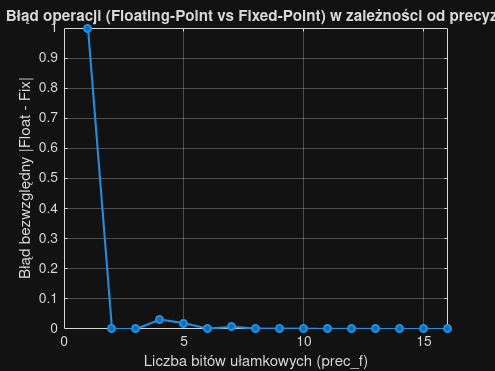

add_mult_two_ways(A, B, C, 1, 1)

% Parametry formatu
sign = 1;        % 1 = signed
prec_i = 1;      % bity części całkowitej (bez znaku)
prec_f = 8;      % bity części ułamkowej
word = sign + prec_i + prec_f; % 10

% Przykładowe wartości (zmień według potrzeb)
A_double = 0.32345;
B_double = -0.78743;
C_double = 0.56532;

% Utworzenie fi
A = fi(A_double,sign,word,prec_f);
B = fi(B_double,sign,word,prec_f);
C = fi(C_double,sign,word,prec_f);

% Operacje
S_full = A + B;                 % suma (może być FullPrecision)
S = double(S_full)           % rzutowanie/kwantyzacja do T

S = -0.4648

P_full = (A+B)*C;                 % produkt (FullPrecision)
P = double(P_full);           % rzutowanie do T

P

P = -0.2633

hex(P_full)

ans = '1fbc99'

(A_double+B_double)*C_double

ans = -0.2623

function fix_point_number(number)

sign = 1; %0-unsigned value, 1-signed value % sign
prec_i = 1; %number of integer part bits (Nc) % one bit
prec_f = 8; %number of fractional part bits (Nu) % eight bits
word = sign + prec_i + prec_f; % whole word

n_fix = fi(number,sign,word,prec_f);
n_bin = bin(n_fix);
n_hex = hex(n_fix);
n_double = double(n_fix);

fprintf("\nLiczba: %g, Fix-point: %g, Bin: %s, Hex: 0x%s\n Double: %g\n", number, n_fix, n_bin, n_hex, n_double)
end

function add_two_ways(A, B, sign, prec_i, prec_f)
%0-unsigned value, 1-signed value % sign
%number of integer part bits (Nc) % one bit
%number of fractional part bits (Nu) % eight bits

word = sign + prec_i + prec_f; % whole word

floating_add = A + B;

fix_A = fi(A,sign,word,prec_f);
fix_B = fi(B,sign,word,prec_f);
fixed_add = fix_A + fix_B;


fprintf("\nAdded floating-point: %g\nAdded fixed-point: %g\n", floating_add, fixed_add);
end

function add_mult_two_ways(A, B, C, sign, prec_i)
%0-unsigned value, 1-signed value % sign
%number of integer part bits (Nc) % one bit
%number of fractional part bits (Nu) % eight bits

res = zeros(1,17);

for prec_f = 0:16
    word = sign + prec_i + prec_f; % whole word

    fix_A = fi(A,sign,word,prec_f);
    fix_B = fi(B,sign,word,prec_f);
    fix_C = fi(C,sign,word,prec_f);

    floating_add_mult = (A + B) * C;
    fixed_add_mult = (fix_A + fix_B) * fix_C;

    res(prec_f+1) = abs(floating_add_mult - fixed_add_mult);
end

plot(res, '-o', 'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerFaceColor', '#0072BD');
title('Błąd operacji (Floating-Point vs Fixed-Point) w zależności od precyzji');
xlabel('Liczba bitów ułamkowych (prec\_f)');
ylabel('Błąd bezwzględny |Float - Fix|');

grid on;
xlim([0 16]);
end